# ME5554/AOE5754/ECE5754 Applied Linear Systems - Final Project

Samuel Kramer

11/20/2023

Due: 12/08/2023

% --Setup system
    clear; clc; format compact; close all; warning off;

    % --Comment out if not on Ubuntu Machine:
    % cd("/home/samkramer/Desktop/Engineering/Course Work/ME 5554 -- Applied Linear Systems/ME 5554 -- Final Project")

% --Define max control inputs from previous project
    u1_max = 1959.957;
    u2_max = 1941.943;

## Problem 1 [2 pts].  Prepare the Open-Loop Plant

*The state-space LTI object you developed in the Midterm Project for the open-loop plant should have been saved in a  .mat file.  Before you work on the Final Project, you are responsible for correcting any errors you had in your open-loop plant!  You are NOT allowed to regenerate the open-loop LTI state-space plant in this LiveScript!!!  The open-loop plant MUST be loaded from a .mat file.*

* After loading the .mat file, display the open-loop numerical state-space model.  This model MUST display appropriately chosen statenames, inputnames (ok to use defaults here), and outputnames.*

*Next, extract the Aol, Bol, Col, and Dol matrices, but do not display these results (because you already displayed them in the previous step).*

*Compute the open-loop eigenvalues (ol_poles), and the system dimensions (N, M, P).  Assign these quantities to variables for use later in the LiveScript, but do not display them here.*

% --Load in data
    cd("..")
    load("ME 5554 -- Midterm Project\State_Space_System.mat")
    cd("ME 5554 -- Final Project\")
    sys_ol = sys

sys_ol =
 
  A = 
                  x_dot      y_dot  theta_dot          x          y      theta
   x_dot             -1          0          0          0          0      -9.81
   y_dot              0         -3          0          0          0          0
   theta_dot          0          0       -1.6          0          0          0
   x                  1          0          0          0          0          0
   y                  0          1          0          0          0          0
   theta              0          0          1          0          0          0
 
  B = 
              Right Thrust  Left Thruste
   x_dot                 0             0
   y_dot               0.1           0.1
   theta_dot        0.1302        0.0898
   x                     0             0
   y                     0             0
   theta                 0             0
 
  C = 
              x_dot      y_dot  theta_dot          x          y      theta
   x              0          0          0        

% --Declare Open Loop Plant Model
    A = sys.A; B = sys.B; C = sys.C; D = sys.D;

% --Compute OL poles and the system dimensions M,N,P
    ol_poles = flip(sort(eig(A)));          % Open Loop Poles (greatest to least)
    N = length(A);                          % N states
    M = width(B);                           % M inputs
    P = height(C);                          % P outputs

## Problem 2 [5 pts].  Simulate Closed-Loop Control

*You are given the following set of desired closed-loop poles which are known to result in 5% settling times (transient times) that are less than 3 seconds without saturating any of the control signals.*

cl_poles = [
    -29 + 15i
    -29 - 15i
    -32 + 0i
    -1.6 + 0.76i
    -1.6 - 0.76i
    -1.2 + 0i];

*Use the *`PLACE`* function to compute the full state feedback control gain matrix, and display your result.*

% --Place poles and define G
    G = place(A, B, cl_poles)

G = 1.0e+04 *

   -0.6846   -0.0686    0.1223   -0.9582   -0.0741    3.2651
    0.7239    0.0993   -0.1126    1.0149    0.1122   -3.4203


% --Redefine System
        Acl = A - B*G;

        C = [0 0 0 1 0 0;
             0 0 0 0 1 0;
             0 0 0 0 0 1];
        D = [0 0;
             0 0;
             0 0]; 

        C = C - D*G;
        Ccl = [C;
            -G];

        sys_cl = ss(Acl,[],Ccl,[]);

% --Define state space system names
    sys_cl.StateName = ["x_dot";
                     "y_dot";
                     "theta_dot";
                     "x";
                     "y";
                     "theta"];
    sys_cl.OutputName = ["x"; "y"; "theta";"u1";"u2"];
    sys_cl

sys_cl =
 
  A = 
                  x_dot      y_dot  theta_dot          x          y      theta
   x_dot             -1          0          0          0          0      -9.81
   y_dot          -39.3     -33.72     -9.663     -56.64      -38.2      155.2
   theta_dot      241.3     0.1215     -59.68      336.3     -4.384      -1180
   x                  1          0          0          0          0          0
   y                  0          1          0          0          0          0
   theta              0          0          1          0          0          0
 
  B = 
     Empty matrix: 6-by-0
 
  C = 
               x_dot       y_dot   theta_dot           x           y       theta
   x               0           0           0           1           0           0
   y               0           0           0           0           1           0
   theta           0           0           0           0           0           1
   u1           6846       685.9       -1223        9582     

% --Check that the poles are correct
    flip(sort(eig(Acl)))

ans =  -29.0000 +15.0000i
 -29.0000 -15.0000i
 -32.0000 + 0.0000i
  -1.6000 + 0.7600i
  -1.6000 - 0.7600i
  -1.2000 + 0.0000i


*Assume that the actual plant starts with the following initial conditions (NOTE:  These are NEW IC's!!!):*

% --Define initial conditions
    x0 = -2;            % meters
    x0dot = 0.5;        % meters/sec
    y0 = 1;             % meters
    y0dot = 0;          % meters/sec
    theta0 = -0.5;      % radians
    theta0dot = 0.1;    % radians/sec

    initials = [x0dot;
                y0dot;
                theta0dot;
                x0;
                y0;
                theta0];

*Assume that you have access to the full state vector, then construct a closed-loop state-space LTI object using the feedback gains from above.  You must augment the output equation to output the original outputs as well as the control signals.  Simulate the initial value response using *`INITIAL`*.  Choose a final simulation time of 4 seconds for this simulation.  Estimate the 5% settling times for each output.  Generate a plot like what was required for the Midterm Project with the three outputs on the left-hand side (separate axes for each output), and the control signals on the right-hand side of the figure (separate axes for each control signal).  Annotate each plot with some kind of marker for the 5% settling times, the min and max allowable control signals, grid lines, axis labels, and units.*

% --Simulate Response of Design
    [y,t] = initial(sys_cl, initials, 100);

% --Plotting the outputs new response
    figure()
    subplot(3,2,1)
    plot(t, y(:,1))
        hold on
        grid on
        xlim([0 15])
        ylabel("x (m)")

    subplot(3,2,3)
    plot(t, y(:,2))
        hold on
        grid on
        xlim([0 15])
        ylabel("y (m)")

    subplot(3,2,5)
    plot(t, y(:,3))
        hold on
        grid on
        xlim([0 15])
        xlabel('Time (s)')
        ylabel("\theta (rad)")

    subplot(2,2,2)
    plot(t, y(:,4))
        hold on
        grid on
        xlim([0 5])
        ylabel("u_1 (N)")
        yline(u1_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u1_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u1_max-200 u1_max+200])

    subplot(2,2,4)
    plot(t, y(:,5))
        hold on
        grid on
        xlim([0 5])
        str = "Closed Loop Response";
        sgtitle(str)
        xlabel("Time (s)")
        ylabel("u_2 (N)")
        yline(u2_max,'--','Color',[0.8 0.2 0.2])
        yline(-1*u2_max, '--','Color',[0.8 0.2 0.2])
        ylim([-u2_max-200 u2_max+200])
        
% --Finding the settling times
    xx = lsiminfo(y(:,1),t);     % X values
    yy = lsiminfo(y(:,2),t);
    tt = lsiminfo(y(:,3),t);
    uu1 = lsiminfo(y(:,4),t);
    uu2 = lsiminfo(y(:,5),t);

% --Making Table of values
    settling_times = [xx.TransientTime;
                      yy.TransientTime;
                      tt.TransientTime;
                      uu1.TransientTime;
                      uu2.TransientTime];
    var_names = {'X';'Y';'Theta';'U1';'U2'};
    T = table(settling_times,VariableNames="Settling Times (s)",RowNames = var_names);
    display(T)

T = 5×1 table
             Settling Times (s)
             __________________
    X              2.5644      
    Y              3.1837      
    Theta          2.6194      
    U1            0.43017      
    U2            0.63891      

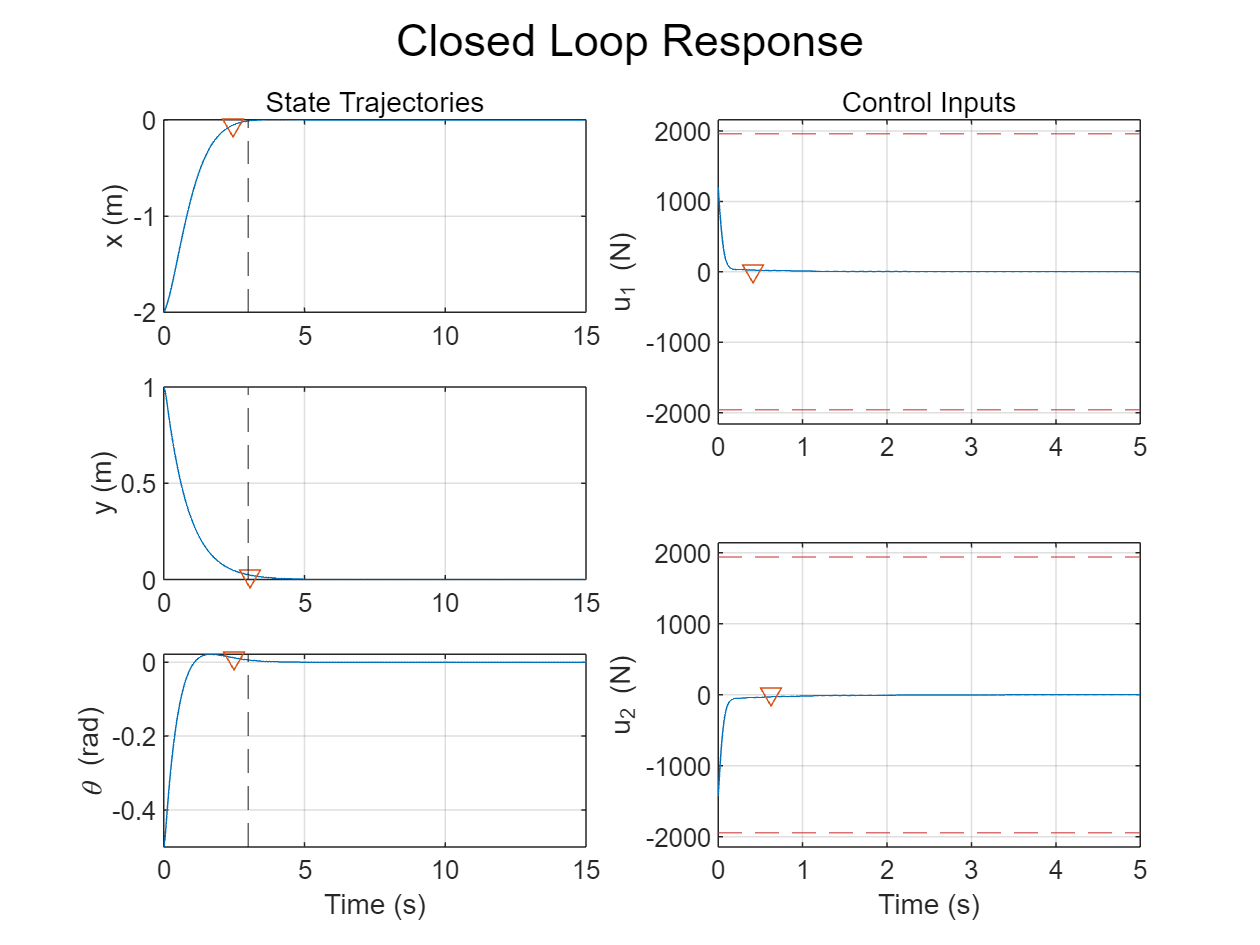


% --Plotting onto subplots
    idx = find(abs(t - xx.TransientTime) < 0.1);
    idx = min(idx);
    subplot(3,2,1)
    plot(t(idx),y(idx,1),'V')
    xline(3,'--')
    subtitle('State Trajectories')

    idx = find(abs(t - yy.TransientTime) < 0.1);
    idx = min(idx); 
    subplot(3,2,3)
    plot(t(idx),y(idx,2),'V')
    xline(3,'--')

    idx = find(abs(t - tt.TransientTime) < 0.1);
    idx = min(idx);
    subplot(3,2,5)
    plot(t(idx),y(idx,3),'V')
    xline(3,'--')

    idx = find(abs(t - uu1.TransientTime) < 0.01);
    idx = min(idx);
    subplot(2,2,2)
    plot(t(idx), y(idx,4),'V')
    subtitle('Control Inputs')

    idx = find(abs(t - uu2.TransientTime) < 0.01);
    idx = min(idx);
    subplot(2,2,4)
    plot(t(idx), y(idx, 4), 'V')

*Include the animation plot in the LiveScript as documentation of the performance.*

% --Setup Animation
    t_vector = 0:0.1:3;
    x_vector = linspace(x0,0,length(t_vector));
    y_vector = linspace(y0,0,length(t_vector));
    theta_vector = linspace(theta0,0,length(t_vector));

% --Animate [UNCOMMENT TO RUN]
    % als_f23_animate(t_vector, x_vector, y_vector, theta_vector)

## Problem 3 [2 pts].   Evaluate Observability

*First show that this system is completely observable using all three outputs.  Then determine whether this system is completely observable using any subset of outputs.  Justify your answers.*

% --Determine observability of full system
    O = ctrb(A',C');
    rank(O)

ans = 6

    rank(O) == N

ans = logical
   1

Therefore, with all three outputs we have a fully observable system because the rank of the observer matrix O is equal to the number of states N in our system (6).

% --Determine observability with only one of the outputs available
    sset = nchoosek(1:P,1);
    for i = 1:P

        % --Changing Ccl matrices
            Ccl_subset = [C(sset(i),:)];
            fprintf("New closed loop C output matrix will look like: \n")
            disp(Ccl_subset)

        % --Testing controlability
            O = ctrb(A', Ccl_subset');
            fullrank = length(A) - rank(O);

        % --Output solutions
            if fullrank == 0
                fprintf("\n \nThe system is completely observable with only output %1.0f. \n", i)

            else
                fprintf("The system is not completely observable with only output %1.0f. \n", i)
            end
            fprintf("Rank of observability martix is %1.0f",rank(O))
            fprintf("\n \n \n")

    end

New closed loop C output matrix will look like: 


     0     0     0     1     0     0


The system is not completely observable with only output 1. 


Rank of observability martix is 4

New closed loop C output matrix will look like: 


     0     0     0     0     1     0


The system is not completely observable with only output 2. 


Rank of observability martix is 2

New closed loop C output matrix will look like: 


     0     0     0     0     0     1


The system is not completely observable with only output 3. 


Rank of observability martix is 2

Therefore with only any of the three outputs available we do not have an observable system because the rank of the observability matrix O is not equivalent to the number of states N in our system (6). 

% --Determine Observability with only 2 outputs
    sset = nchoosek(1:P,2);
    for i = 1:P

        % --Changing Ccl matrices
            Ccl_subset = [C(sset(i,1),:); C(sset(i,2),:)];
            fprintf("New closed loop C output matrix will look like: \n")
            disp(Ccl_subset)

        % --Testing controlability
            O = ctrb(Acl', Ccl_subset');
            fullrank = length(A) - rank(O);

        % --Output solutions
            if fullrank == 0
                fprintf("\n \nThe system is completely observable with only outputs %1.0f and %1.0f. \n", sset(i,1), sset(i,2))

            else
                fprintf("The system is not completely observable with only output %1.0f. \n", i)
            end
            fprintf("Rank of observability martix is %1.0f",rank(O))
            fprintf("\n \n \n")

    end

New closed loop C output matrix will look like: 


     0     0     0     1     0     0
     0     0     0     0     1     0



 
The system is completely observable with only outputs 1 and 2. 


Rank of observability martix is 6

New closed loop C output matrix will look like: 


     0     0     0     1     0     0
     0     0     0     0     0     1



 
The system is completely observable with only outputs 1 and 3. 


Rank of observability martix is 6

New closed loop C output matrix will look like: 


     0     0     0     0     1     0
     0     0     0     0     0     1



 
The system is completely observable with only outputs 2 and 3. 


Rank of observability martix is 6

Our system is fully observable with any combination of only two of the sensor outputs in our system because the rank of the observability matrices in any of the systems is equivalent to the number of states in our system (6).

## Problem 4 [3 pts].  Design a Full-Order Luenberger Observer

*In this problem, you will compute the gains for a state estimator using all three outputs. You must first choose appropriate pole locations for the state estimator (observer), and then compute and display the associated feedback gain matrix using the *`PLACE`* function.*

For this problem we are trying to determine the optimal pole locations for the dynamic state estimator system. To do this we want to drive the derivative of the error to 0.


$$\dot{e(t)} = [A - KC] e(t)$$


Where our poles are at the given locations:


$$[sI - A^T + KC^T] = 0$$


Classical control theory says that we need the pole locations to be to the left of the controller poles from the $A - BG$ matrix to converge properly to the desired values.

% --Choose ideal pole locations for the state estimator
    observer_poles = [-33 + 15i;
                      -33 - 15i;
                      -35 + 0i;
                      -6 + 0.76i;
                      -6 - 0.76i;
                      -5 + 0i];
    
% --Derive observer gain matrix K 
    K = place(A', C', observer_poles)'

K =    49.3248 -118.1246   22.3375
   45.8076   97.9329   -1.7072
  -67.8169  -26.5461  169.1348
   20.4627  -23.7568   -0.0528
   21.3180   52.8159    2.6948
  -11.7321  -10.7613   39.1214


*To document your design, you must generate a plot that includes the open-loop poles from Problem 1, the closed-loop poles from Problem 2, and observer poles from this problem.  Use common markers for each set of poles (i.e. all open-loop poles must use the same marker, etc.) so that it is easy to distinguish the poles on the figure.  Include a legend that only has three entries in it (open-loop, closed-loop, observer), corresponding to the three sets of poles.  You must use the *`SGRID`* function (read the Matlab help!!) to generate appropriate grid lines.  Annotate your plot with axis labels.  Make sure your legend does not cover up any of the poles!*

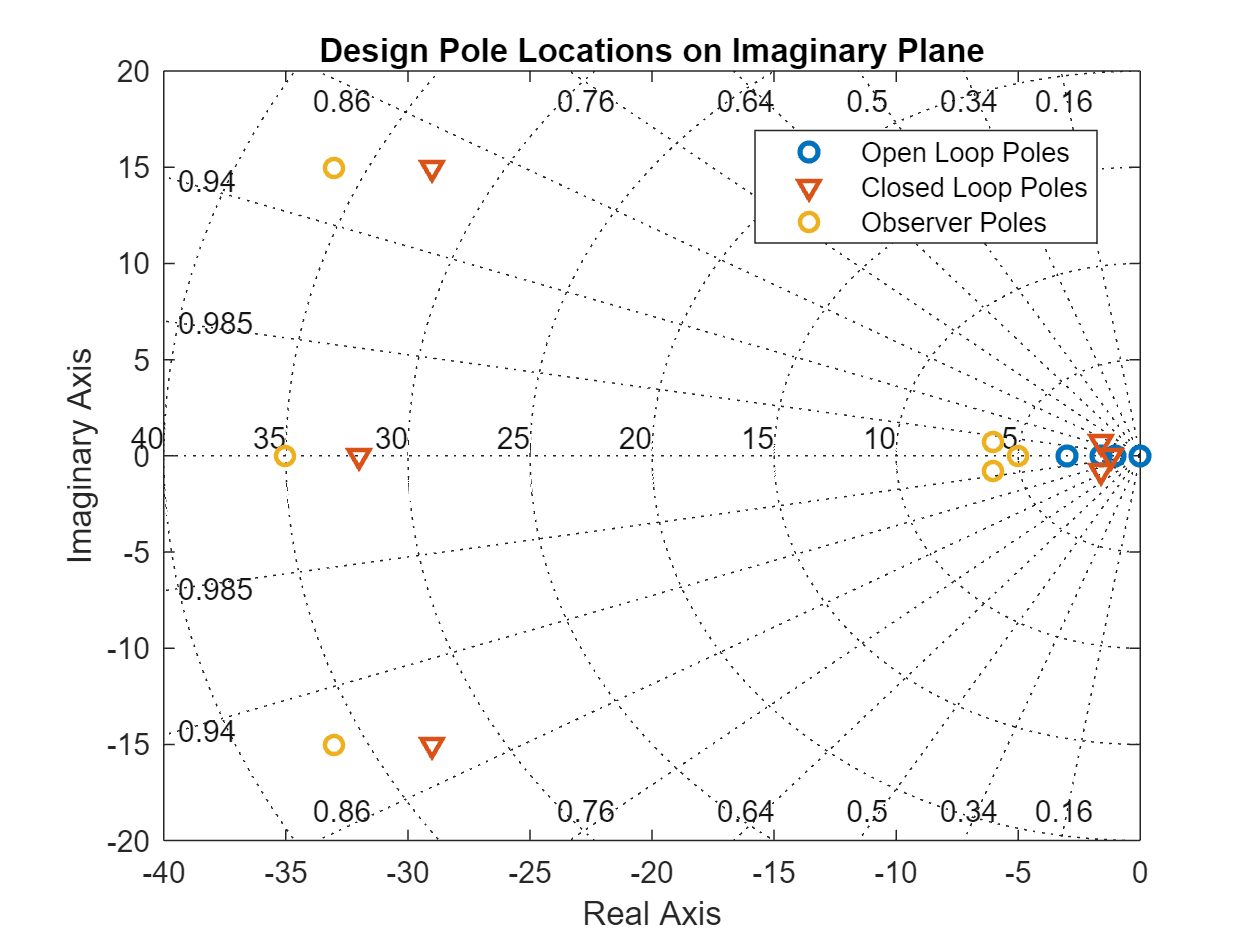

% --Creating OL Pole plot
    figure()
    plt1 = plot(real(ol_poles), imag(ol_poles), 'o', "LineWidth", 1.75);
        hold on
        xlabel('Real Axis')
        ylabel('Imaginary Axis')
        title("Design Pole Locations on Imaginary Plane")
        xlim([-40 0])
        ylim([-20 20])

    plot(real(cl_poles), imag(cl_poles), "V", "LineWidth", 1.5)

    plot(real(observer_poles), imag(observer_poles), "o", "LineWidth", 1.5)
        legend("Open Loop Poles", "Closed Loop Poles", "Observer Poles","Autoupdate","off", "Position", [0.59944,0.74328,0.27143,0.11905])
        sgrid

## Problem 5 [10 pts].  Simulate Output Feedback Control

*For this problem, you must simulate the complete output feedback control system, which will include the state estimator and full state feedback using the estimated states. In order to insure that the estimated states *$\hat{\mathbf{x}}$* (and outputs *$\hat{\mathbf{y}}$*) have converged before control is enabled, you will first need to generate an augmented LTI closed-loop output-feedback control model with the state feedback gain *$\mathbf{G}$* set to zero (it is easier to just use *$\left(0*\mathbf{G}\right)$* in the matrices).  This first LTI object will be used for the first ****200 milliseconds**** of the response.  You must use the same initial states on the plant as defined in Problem 2 above, but the initial observer states must be zero.  Your closed-loop state-space output equation must also be augmented to output the following three vectors:  *$\mathbf{y}$*, *$\hat{\mathbf{y}}$*, and *$\mathbf{u}$*.*

For this we are going to be doing the initial no-control section of our simulation where we want to allow our estimator error to converge to zero. This means that our t_max will be set to 0.2 seconds and we will have to set our system to have a feedback control of 0. From here we can generate the state equation with the Luenberger observer implemented below for our open loop system. 

State equation:

$\left\lbrack \begin{array}{c}
\dot{x} \\
\hat{\dot{x} } 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cc}
A & 0\\
\mathrm{KC} & \hat{A} -K\hat{C} 
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$+$\left\lbrack \begin{array}{c}
B\\
\hat{B} +K\left(D-\hat{D} \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
u\\
u
\end{array}\right\rbrack$

But this is open loop and we want a closed loop system, we can then substitute in our control law $u(t) = -G\hat{x}$ we get the following

$\left\lbrack \begin{array}{c}
\dot{x} \\
\hat{\dot{x} } 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cc}
A & -\mathrm{BG}\\
\mathrm{KC} & \hat{A} -K\hat{C} -\mathrm{BG}-K\left(D-\hat{D} \right)G
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$

I think that because we are in simulation world, the state and output equations for our system A and our simulation $\hat{A}$ are going to be the same. Our values for $D$ and $\hat{D}$ are going to cancel out because we have both set as 0 because there is no direct passthrough in our system. Our output equations then become the following:

$\left\lbrack \begin{array}{c}
y\\
\hat{y} 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{cc}
C & -\mathrm{DG}\\
0 & \hat{C} -\hat{D} G
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
x\\
\hat{x} 
\end{array}\right\rbrack$

% --Initial Observer Values
    O_0 = zeros(3,1);
    G_0 = 0.*G;

% --Setup the following system
    Aof = [A, -B*G_0;
           K*C, A - K*C - B*G_0 - K*(D-D)*G_0];         % Which yields a 12x12 matrix
    Cof = [C, -D*G_0;
           zeros(3,6), C-D*G];                          % Which is a 6x12 Matrix

Next, you must generate a second augmented LTI closed-loop output-feedback control model that is identical to the first model except that the state-feedback control gains are not zero, i.e. the controller is enabled.  This second LTI object will be used for the remainder of the simulation.

You are now ready to simulate the closed-loop response, but it must happen in two separate simulation stages.  In the first stage, you will use the INITIAL function to simulate for 200 milliseconds.  At the end of this first simulation stage, you must capture the final state vector and use it as the initial state vector for the second simulation stage.  The total simulation duration should be 4 seconds like above.

Generate the standard annotated plot (three output subplots on the left and two control signal subplots on the right), with appropriate annotations; but you must also plot the estimated output signals on top of the associated actual output signals.  It must be clear from your plots that the estimated outputs all start from zero and converge to the actual outputs within 200 milliseconds.  Do NOT try to get the observer states to converge too fast because it will be difficult to see the convergence on the plots.  If you have done this step correctly, you should see 5% settling times that are comparable to the original design from Problem 2.  The 5% settling times on the outputs must all be below 3 seconds, and you must not saturate either of the control signals.

In addition to the normal five subplot figure, you must also include the animation plot in the LiveScript as documentation of the performance.

### For problems 6, 7, and 8, you will design and simulate another Output Feedback Controller (i.e. a state estimator with full state feedback control), but now you must also include Integral Control for reference tracking as defined in the notes.  

### This closed-loop simulation will require you to redesign the state-feedback control gains $\mathbf{G}$ (you cannot use the gains from Problem 2!); however, you should plan to use the same state estimator gains $\mathbf{K}$you designed in Problem 4.  You are welcome to redesign the state estimater gains (poles), but this is not recommended because it will add unnecessary time to your project completion.

### You must expect to iterate on problems 6, 7, and 8 until you achieve one acceptable design.

## Problem 6 [10 pts].  Design an LQI compensator

You must use LQR optimal control to design the state-feedback gains for this simulation.  The MathWorks has provided a separate tool called `LQI` for computing the state-feedback gains when you are implementing state feedback with integral control.  Note that `LQI` is identical to `LQR` except that `LQI` already knows that you are designing for reference tracking with an integral controller.  You can NOT use `LQR` for this design, and you must use `LQI!`  You must also use the LTI object for the open-loop system as input to the `LQI` function.  Read the online help for `LQI` before starting this problem!

First define the LQI cost function weighting matrices $\mathbf{Q}$ and $\mathbf{R}$.  Note that `LQI` also accepts a weighting matrix $\mathbf{N}$, which allows cross-weighting between states and controls, but you should NOT use this weighting matrix for this problem!  Make sure you understand the dimensions of each of these weighting matrices.

Generate and display the optimal control gains and separate them into ${\mathbf{G}}_0$ and ${\mathbf{G}}_I$ matrices.

## Problem 7 [15 pts].  Construct the OFC with Reference Inputs

Generate an augmented state-space system for the closed-loop Output Feedback Controller (state feedback with estimated states) and Reference Tracking.  Your complete closed-loop state-space model must have:

- State vector consisting of:  $\mathbf{x}$, $\hat{\mathbf{x}}$, and ${\mathbf{x}}_I$

- Output vector consisting of:  $\mathbf{y}$, $\hat{\mathit{\mathbf{y}}}$, and $\mathbf{u}$

- Input vector consisting of:  $\mathbf{r}$

- State Feedback Control law:  $u=-\left\lbrack \begin{array}{cc}
{\mathbf{G}}_0  & {\mathbf{G}}_I 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\hat{\mathbf{x}} \\
{\mathbf{x}}_I 
\end{array}\right\rbrack$

After generating the closed-loop output feedback control state-space model, compute and display the closed-loop eigenvalues.

## Problem 8 [10 pts].  Simulate the Output Feedback Controller with Reference Inputs

For this problem, you will simulate the closed-loop response of your control system using `LSIM()`; however, you must first generate a suitable reference profile as an input.  Before you can generate a reference profile, you need to understand the initial position and the final desired position of the drone.  These are new initial conditions, and a very different final position from any closed-loop simulation you have done before.

**Initial Plant Conditions:**  The plant (drone) must start with the following initial states:

    $x\left(0\right)=-2$ m, $y\left(0\right)=1$ m, and $\theta \left(0\right)=0$ rad.

    $\dot{x} \left(0\right)=0$ m/s, $\dot{y} \left(0\right)=0$ m/s, and $\dot{\theta} \left(0\right)=0$ rad/s.

**Initial Observer Conditions:**  You may assume that the initial observer states are identical to the initial plant states.

**Final Plant Conditions:**  The plant (drone) must reach the following final states:

    $x\left(0\right)=+2$ m, $y\left(0\right)=0$ m, and $\theta \left(0\right)=0$ rad.

    $\dot{x} \left(0\right)=0$ m/s, $\dot{y} \left(0\right)=0$ m/s, and $\dot{\theta} \left(0\right)=0$ rad/s.

**Evaluation Criteria:**

- Notice that the final state is on the opposite side of the 1.5m high red wall in the animation!  The drone is NOT allowed to make contact with the wall at any point during the simulation.  

- The drone is NOT allowed to make contact with the ground at any point during the simulation except for the final time where the drone must sit on the ground.

- The drone must reach the final state by 30 seconds ($\textrm{tfinal}\le 30s$).

- The control signals $u_1$ and $u_2$ must remain within the saturation bounds established in the Midterm Project.

- There is NO formal settling time requirement; however, your actual output responses $\mathbf{y}$ must track the reference responses $\mathbf{r}$reasonably accurately.  For example, if your reference profiles have dwell regions, then there should be zero steady-state error after transients have subsided.  If your reference profiles have ramp regions, then you should expect to see a steady-state error during the ramp, which looks like a delayed response.  How closely you track the references will depend on your choice of weighting coefficients in the Q matrix.  Note that a steady-state error during the ramp is perfectly acceptable as long as you choose the reference profile such that the drone does not make contact with the wall!

- For this simulation, the observer and the controller must both be enabled at t=0 (i.e. do NOT attempt a two-stage simulation like problem 5.

- You MUST use `LSIM` to simulate the closed-loop time response

- Before constructing the reference profiles, you must first construct a time vector for the simulation.  I recommend choosing a uniform step size of $\textrm{ts}=0\ldotp 002$ seconds:


$$t=\textrm{ts}*\left\lbrack 0:\textrm{round}\left(\frac{\textrm{tfinal}}{\left.\textrm{ts}\right)}\right)\right\rbrack$$


- For each time step in the time vector, you must generate a reference vector for each of the outputs.  You will need to generate a particular path vs. time profile for the desired x and y position; however, I recommend choosing the following reference profile for the angular position:


$$\theta_{\textrm{ref}} =\textrm{zeros}\left(\textrm{size}\left(t\right)\right)$$


- You must use the same plot structure as before except that new signals that must be added.  Each of the three output subplots on the left must include the reference profile, the actual output, and the estimated output on the same axis.

- I may decide to give bonus points for solutions that meet all of the criteria above and reach the final state in a minimum time (relative to your classmates).

- In addition to the normal five subplot figure, you must also include the animation plot in the LiveScript as documentation of the performance